# 다변량선형회귀분석 

modelspec = ' cap ~ maxTimeDelta + maxTemp + ohm + re_c + re_d ';

시계열 데이타이지만 각 피쳐와 Capacity는  시계열 모델이 아니라 일반적인 structural 모델이다.

load B0005.mat
load B0006.mat
load B0007.mat
load B0018.mat
BAT1 =B0005;
BAT2 =B0006;
BAT3 =B0007; 
BAT4 =B0018; 


## 피쳐 얻어오기

array2table 로 테이블을 만들때 선형회구를 하기 위해 종속변수를 제일 뒤에 두어라

[cap,maxTemp,maxTimeDelta,abnormal,ohm,re_c,re_d] = extract_feature_v1(BAT1);
%maxTimeDelta(abnormal) <= 이상값을 변경하는 것도 필요하다. 차후에.
dataVectorAll = [  maxTimeDelta' maxTemp' ohm'  re_c' re_d' cap'];
dataVector = [  maxTimeDelta' cap'];

[cap2,maxTemp2,maxTimeDelta2,abnormal2,ohm2,re_c2,re_d2] = extract_feature_v1(BAT2);
dataVectorAll2 = [maxTimeDelta2' maxTemp2' ohm2'  re_c2' re_d2' cap2'  ];
dataVector2 = [maxTimeDelta2' cap2'  ];

[cap3,maxTemp3,maxTimeDelta3,abnormal3,ohm3,re_c3,re_d3] = extract_feature_v1(BAT3);
dataVectorAll3 = [maxTimeDelta3' maxTemp3' ohm3'  re_c3' re_d3' cap3'  ];
dataVector3 = [maxTimeDelta3'  cap3'  ];

%{
% extract_feature function has errors on BAT4
[cap4,maxTemp4,maxTimeDelta4,abnormal4,ohm4,re_c4,re_d4] = extract_feature_v1(BAT4);
dataVectorAll4 = [maxTimeDelta4' maxTemp4' ohm4'  re_c4' re_d4' cap4'  ];
dataVector4 = [maxTimeDelta4' cap4'  ];
%}

#### 백터를 테이블로 저장하기


tbl = array2table(dataVectorAll,...
    'VariableNames',{'maxTimeDelta','maxTemp','ohm','re_c','re_d','cap'});
    
% https://kr.mathworks.com/help/stats/fitlm.html
modelspec = ' cap ~ maxTimeDelta + maxTemp + ohm + re_c + re_d ';
mdl = fitlm(tbl,modelspec )

mdl = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d

Estimated Coefficients:
                          Estimate                   SE                   tStat                 pValue       
                    ____________________    ____________________    _________________    ____________________

    (Intercept)         1.75913510383276       0.109607416778593     16.0494166867029    8.26807791717636e-31
    maxTimeDelta    0.000269766848947027    9.43835667468473e-06      28.581972290853    2.83742510869411e-53
    maxTemp          -0.0118420399464535     0.00166052674122405    -7.13149608040893      1.037350185507e-10
    ohm                -175.133548807257        16.1981044894278    -10.8119779645552    4.31385798931144e-19
    re_c      

mdl.Coefficients

ans = 6×4 table
                          Estimate                   SE                   tStat                 pValue       
                    ____________________    ____________________    _________________    ____________________

    (Intercept)         1.75913510383276       0.109607416778593     16.0494166867029    8.26807791717636e-31
    maxTimeDelta    0.000269766848947027    9.43835667468473e-06      28.581972290853    2.83742510869411e-53
    maxTemp          -0.0118420399464535     0.00166052674122405    -7.13149608040893      1.037350185507e-10
    ohm                -175.133548807257        16.1981044894278    -10.8119779645552    4.31385798931144e-19
    re_c                1.03479213565021       0.424971443001321     2.43496863775619      0.016471402

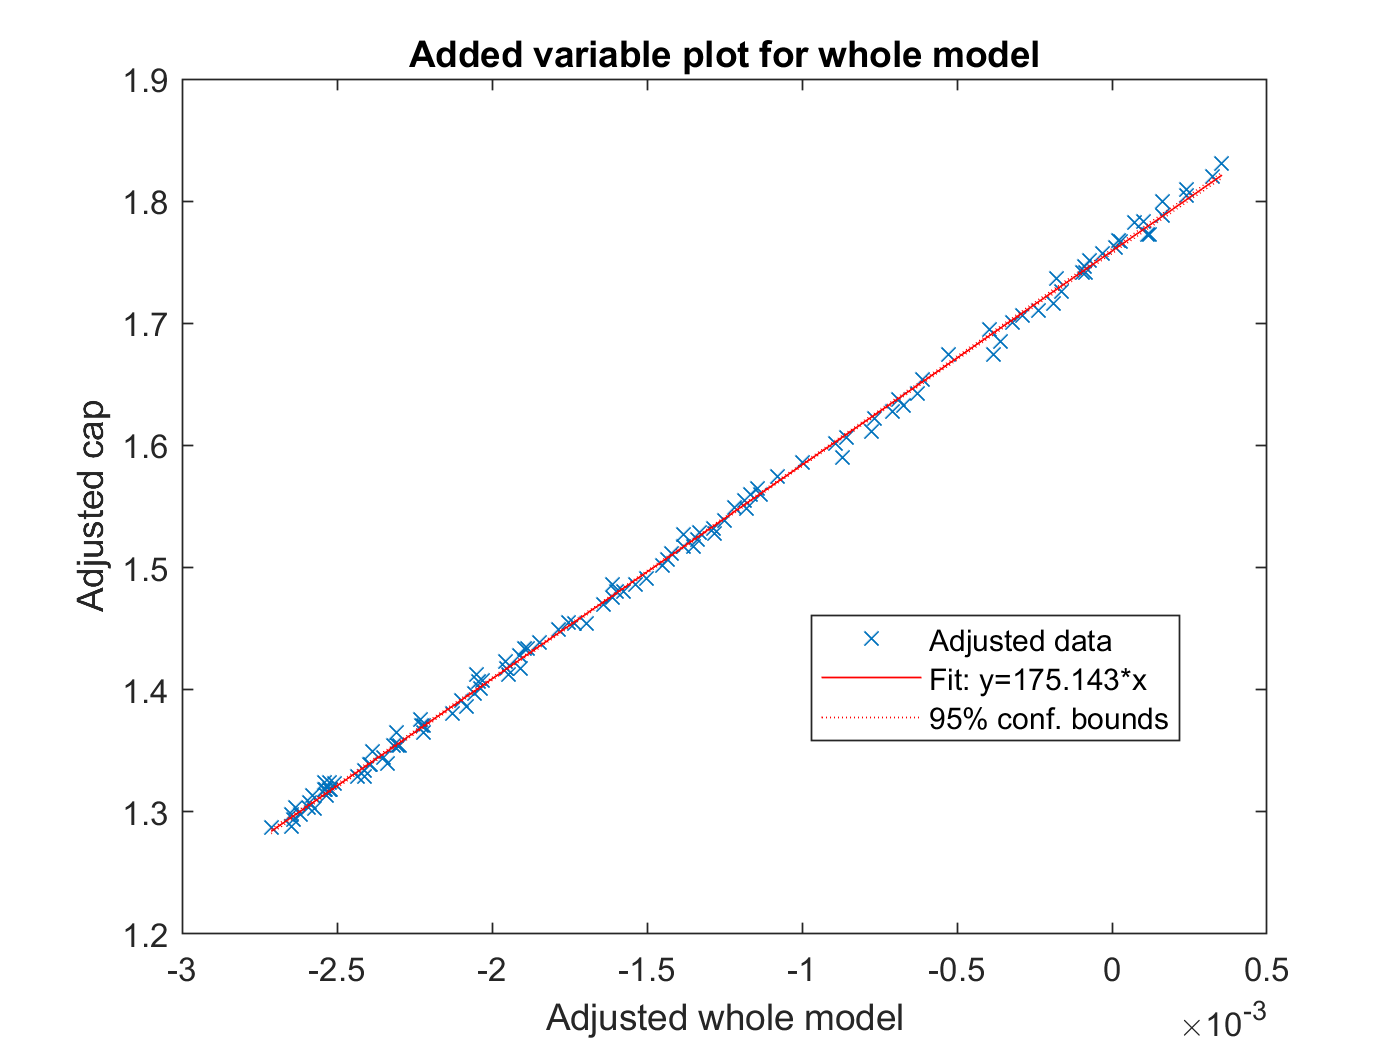

% https://kr.mathworks.com/help/stats/linearmodel.plot.html
plot(mdl)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차이가 많이 난다.

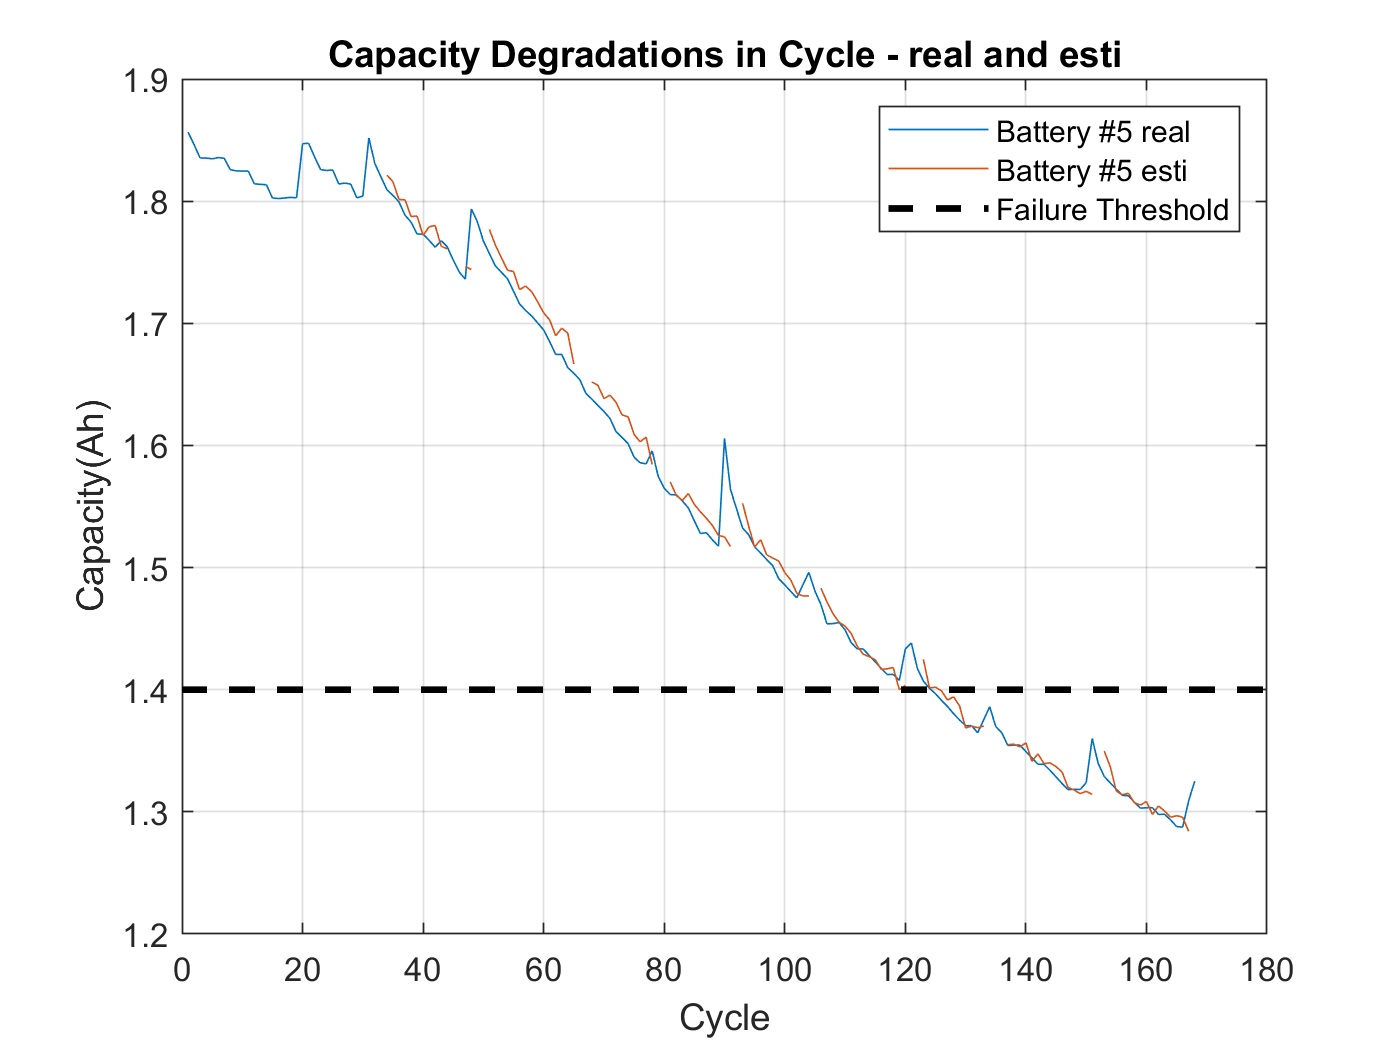

% 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d
cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ... 
    + table2array(mdl.Coefficients(3,1))*maxTemp ... 
    + table2array(mdl.Coefficients(4,1))*ohm ... 
    + table2array(mdl.Coefficients(5,1))*re_c ... 
    + table2array(mdl.Coefficients(6,1))*re_d ;


figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

모델설정후 잔차에 대한 히스토그램을 그린다.

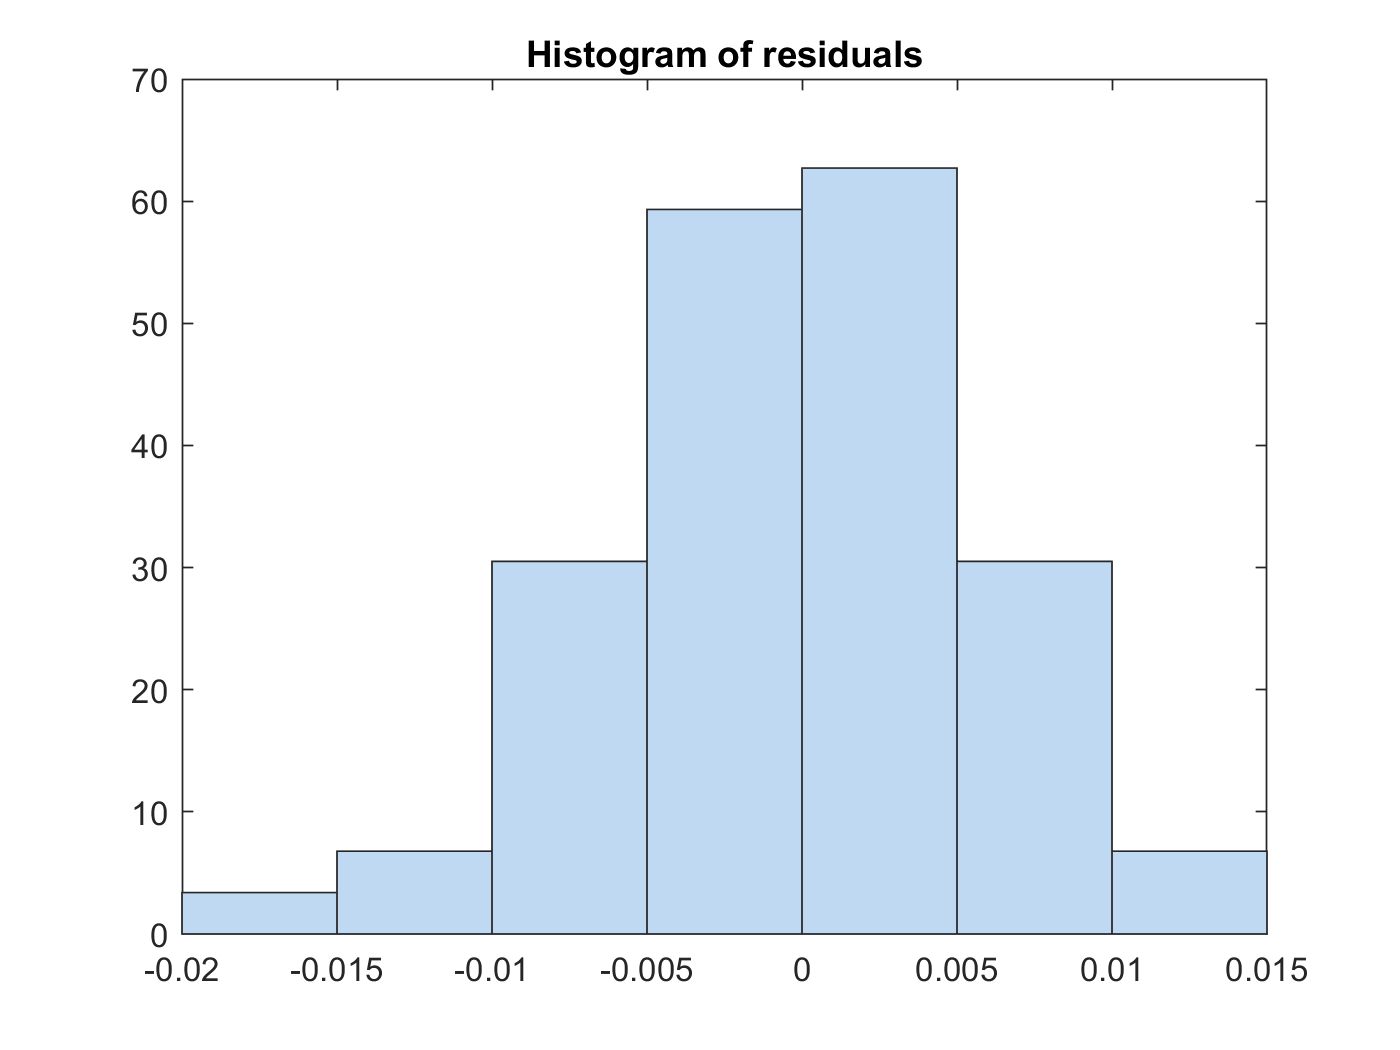

plotResiduals(mdl)

잔차 분포에서 outer를 제거하자

outlier = mdl.Residuals.Raw < -0.015 ;
find(outlier)

ans =     64
    77


모델에 사용된 데이타에서 outer 를 제외하고 모델링하라.

mdl = fitlm(tbl,modelspec,...
    'Exclude',find(outlier));

outer 정보 출력

mdl.ObservationInfo(find(outlier),:)

ans = 2×4 table
    Weights    Excluded    Missing    Subset
    _______    ________    _______    ______

       1        true        false     false 
       1        true        false     false 


outer를 제거 후 회귀선이 잘 그려지는지 확인하자.

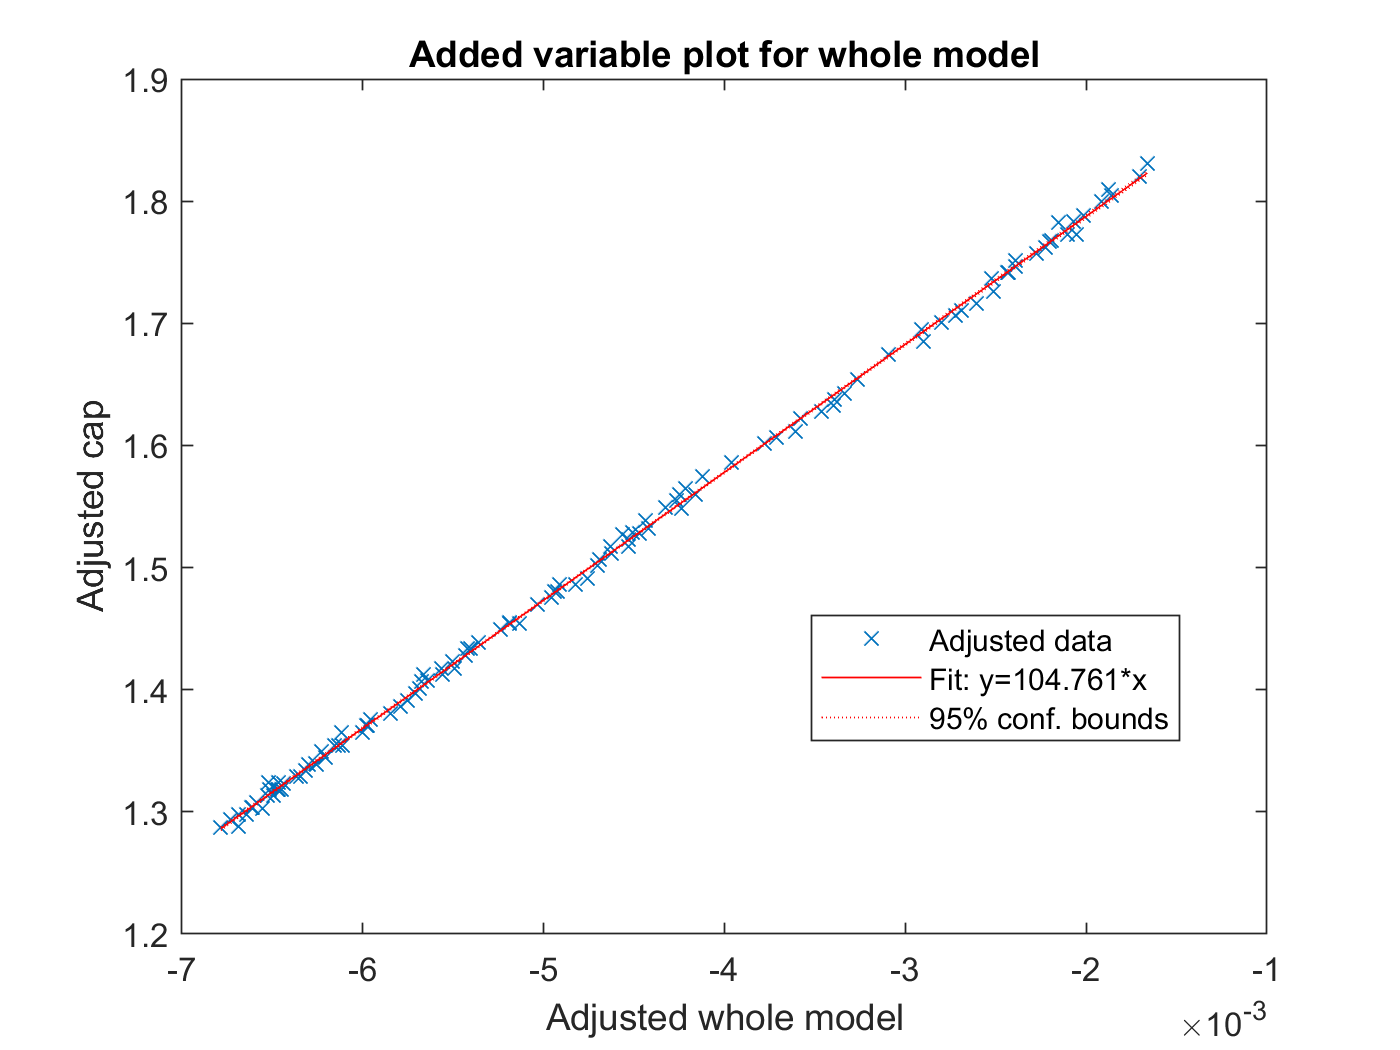

plot(mdl1)

모델링된 선형회구식을 가지고 원래 데이타와 예측한 데이타를 비교하자

차기가 많이 줄어들었다.

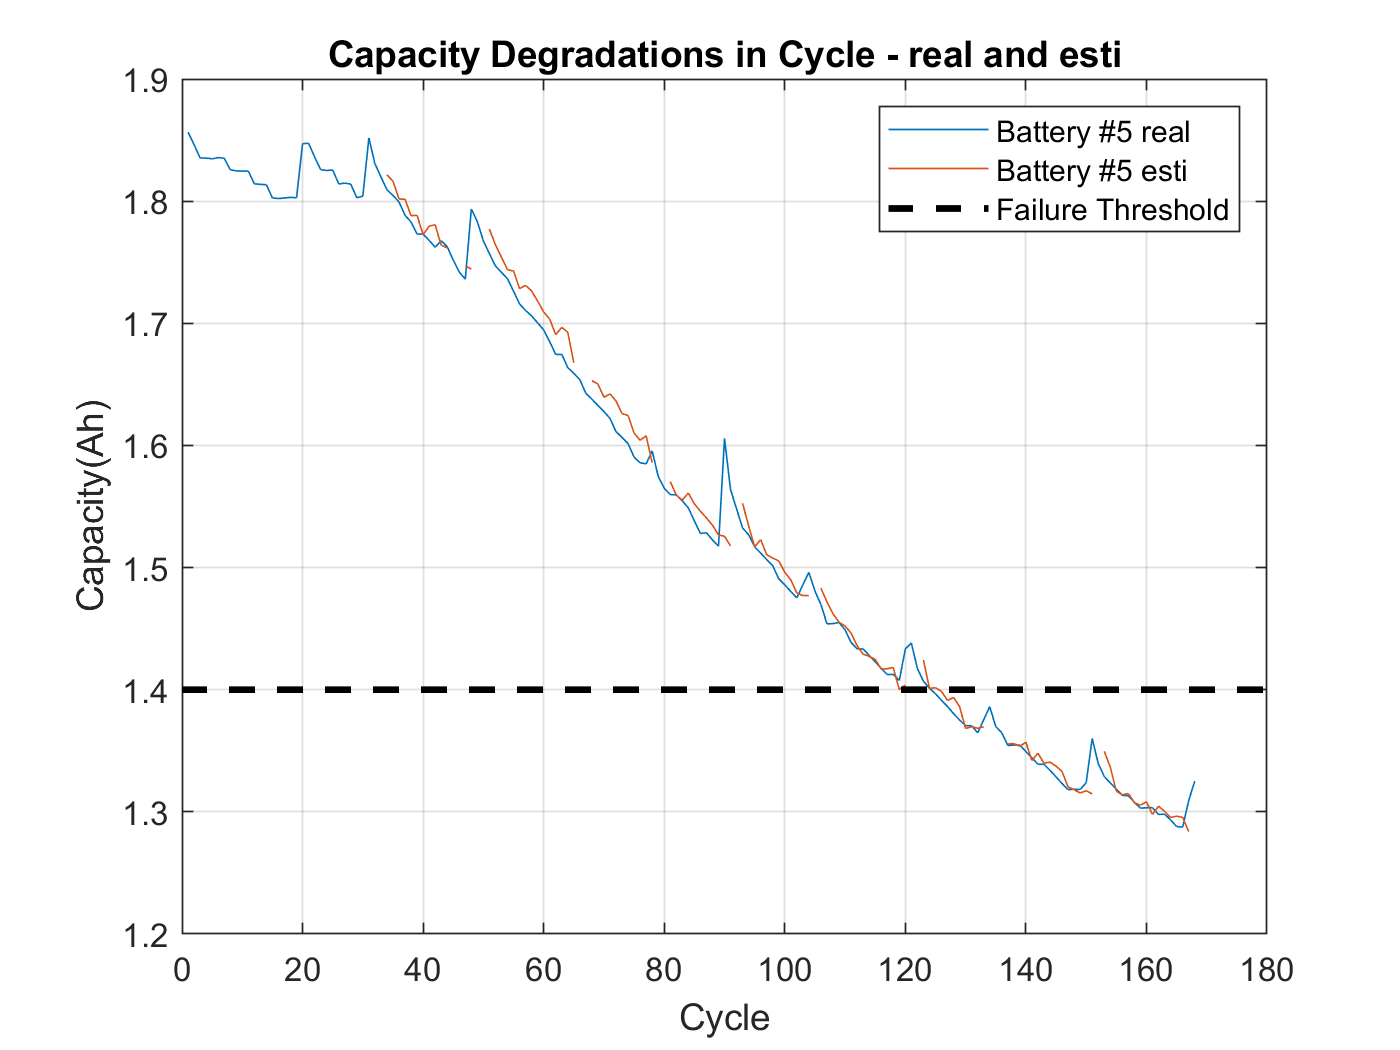

% 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d
cap5hat = table2array(mdl.Coefficients(1,1)) ...
    + table2array(mdl.Coefficients(2,1))*maxTimeDelta ... 
    + table2array(mdl.Coefficients(3,1))*maxTemp ... 
    + table2array(mdl.Coefficients(4,1))*ohm ... 
    + table2array(mdl.Coefficients(5,1))*re_c ... 
    + table2array(mdl.Coefficients(6,1))*re_d ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

아래는 다변량 선형회귀에서 변수를 줄이기 위한 것이다.

mdl1 = step(mdl,'NSteps',10)

1. Adding maxTimeDelta:ohm, FStat = 53.3742, pValue = 4.81651e-11


mdl1 = Linear regression model:
    cap ~ 1 + maxTemp + re_c + re_d + maxTimeDelta*ohm

Estimated Coefficients:
                              Estimate                   SE                   tStat                 pValue       
                        ____________________    ____________________    _________________    ____________________

    (Intercept)             1.99711801907422      0.0887567290132881     22.5010322177964    9.08606676758369e-43
    maxTimeDelta        0.000525409298191937    3.62771422160695e-05     14.4832052939164    3.73091753245824e-27
    maxTemp              -0.0179739529664342     0.00152461291485133    -11.7891910735827    3.53589231103287e-21
    ohm                    -104.749494951533        16.2660920941543    -6.43974559747993    3.31905295113236e-09

plot(mdl1)

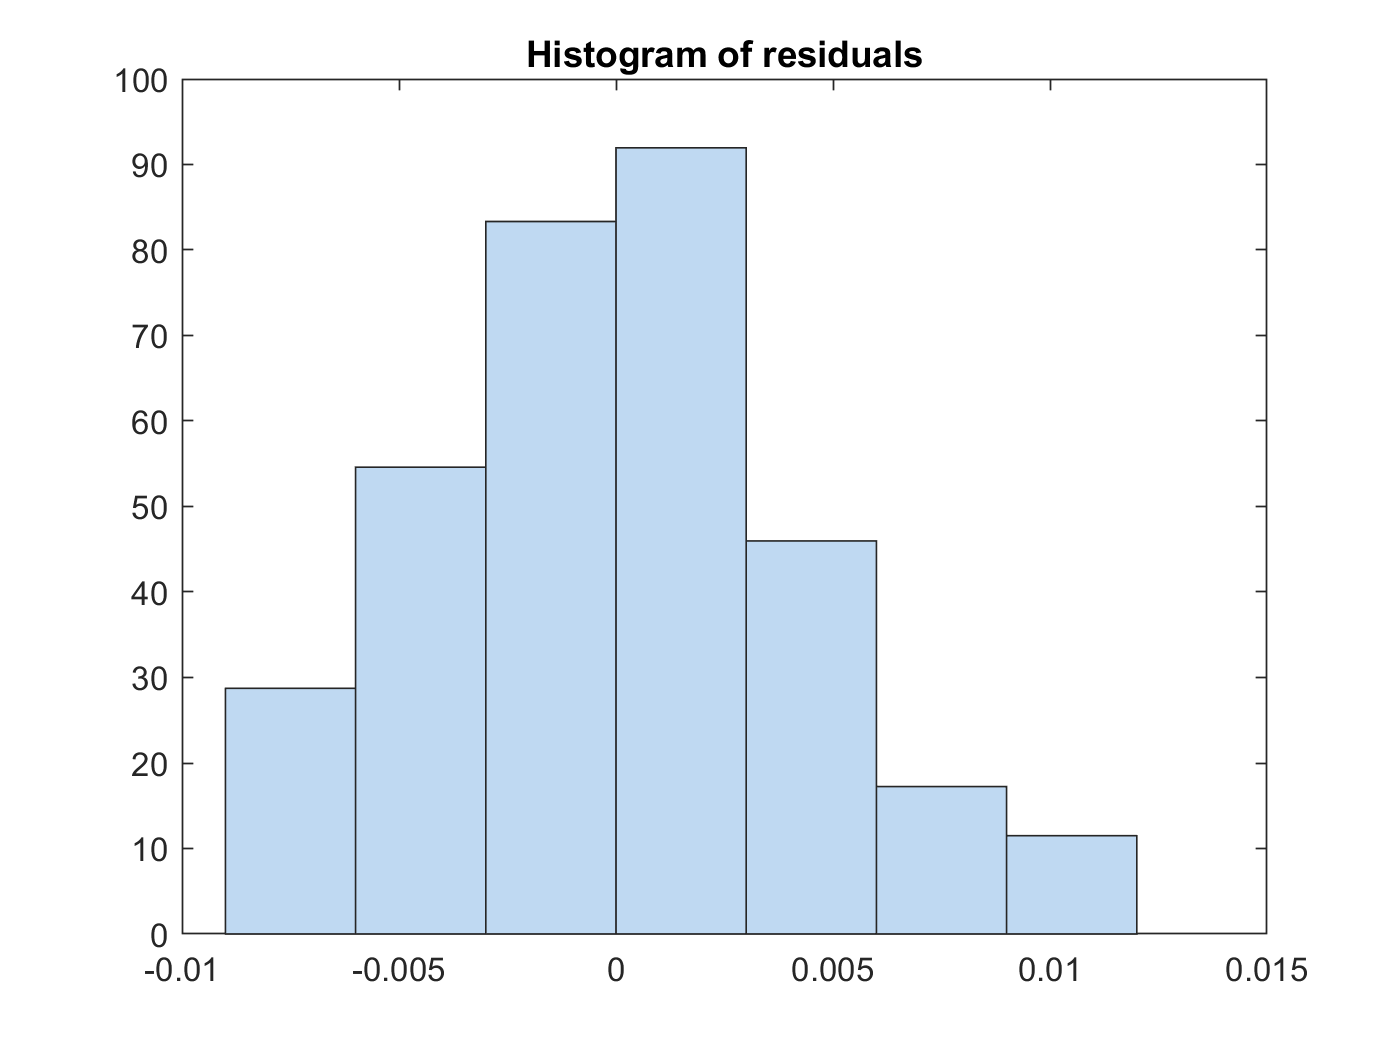

plotResiduals(mdl1)

모델링된 선형회귀식을 가지고 원래 데이타와 예측한 데이타를 비교하자

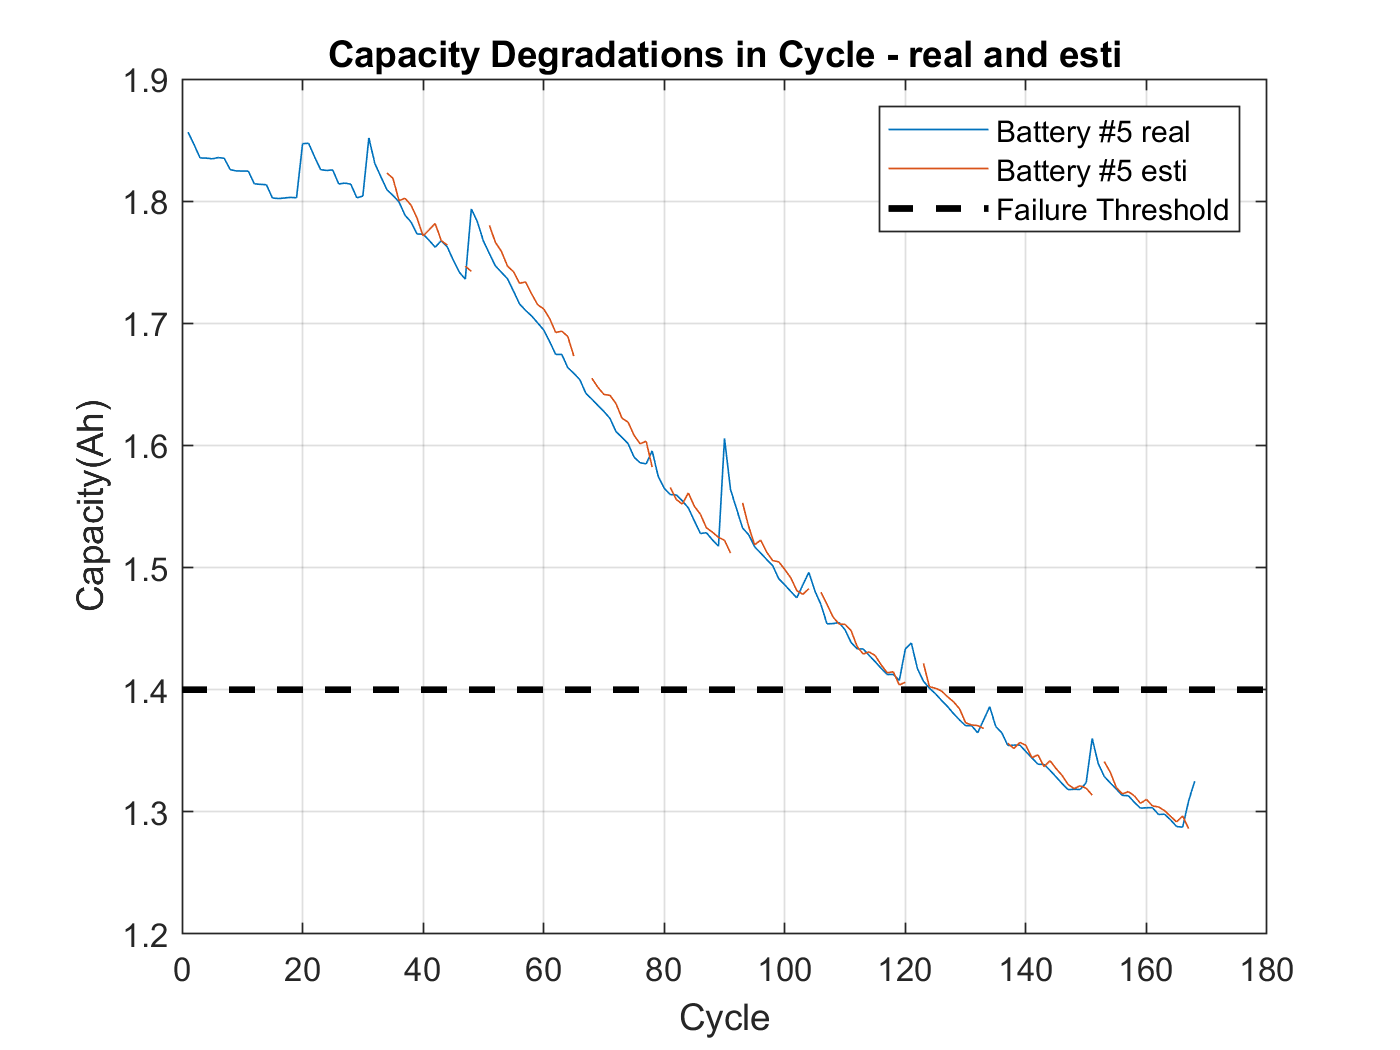

% 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d
cap5hat = table2array(mdl1.Coefficients(1,1)) ...
    + table2array(mdl1.Coefficients(2,1))*maxTimeDelta ... 
    + table2array(mdl1.Coefficients(3,1))*maxTemp ... 
    + table2array(mdl1.Coefficients(4,1))*ohm ... 
    + table2array(mdl1.Coefficients(5,1))*re_c ... 
    + table2array(mdl1.Coefficients(6,1))*re_d ...
    + table2array(mdl1.Coefficients(7,1)).*maxTimeDelta.*ohm ;

figure
plot(cap5), hold on, plot(cap5hat')
plot(0:180, 1.4*ones(1, 181),'k--','LineWidth', 2)
hold off, grid on
xlabel Cycle, ylabel Capacity(Ah)
legend('Battery #5 real', 'Battery #5 esti', 'Failure Threshold')
title('Capacity Degradations in Cycle - real and esti')

4.09585292607480	0.227155110205607	18.0310842330048	7.46164930980593e-41

-0.0952839654207921	0.00835224901979087	-11.4081806223706	1.35336543592271e-22

0.000196894463615833	1.30246355211347e-05	15.1170804969044	5.83185913112480e-33

-82.6228614134608	13.4185717416945	-6.15735139357142	5.43873148600241e-09


lm1 = fitlm(tbl,'linear')

lm1 = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d

Estimated Coefficients:
                          Estimate                   SE                   tStat                 pValue       
                    ____________________    ____________________    _________________    ____________________

    (Intercept)         1.75913510383276       0.109607416778593     16.0494166867029    8.26807791717636e-31
    maxTimeDelta    0.000269766848947027    9.43835667468473e-06      28.581972290853    2.83742510869411e-53
    maxTemp          -0.0118420399464535     0.00166052674122405    -7.13149608040893      1.037350185507e-10
    ohm                -175.133548807257        16.1981044894278    -10.8119779645552    4.31385798931144e-19
    re_c      

lm2 = fitlm(tbl,'interactions')

lm2 = Linear regression model:
    cap ~ 1 + maxTimeDelta*maxTemp + maxTimeDelta*ohm + maxTimeDelta*re_c + maxTimeDelta*re_d + maxTemp*ohm + maxTemp*re_c + maxTemp*re_d + ohm*re_c + ohm*re_d + re_c*re_d

Estimated Coefficients:
                                  Estimate                   SE                   tStat                 pValue       
                            ____________________    ____________________    __________________    ___________________

    (Intercept)                 3.88830547833847        7.53600747638751     0.515963590869788      0.606996508775318
    maxTimeDelta            0.000397122933421928    0.000790505520667053     0.502365793836358      0.616493078992469
    maxTemp                   -0.186582601579383       0.268698661401655    -0.694393491229478       0.489014086

lm3 = fitlm(tbl,'purequadratic')

lm3 = Linear regression model:
    cap ~ 1 + maxTimeDelta + maxTemp + ohm + re_c + re_d + maxTimeDelta^2 + maxTemp^2 + ohm^2 + re_c^2 + re_d^2

Estimated Coefficients:
                            Estimate                    SE                   tStat                  pValue       
                      _____________________    ____________________    __________________    ____________________

    (Intercept)            3.81151288464267        1.18340306848548      3.22080699817742     0.00169348113396745
    maxTimeDelta      -0.000169513537695477    4.97836450133684e-05     -3.40500454817959    0.000932497180717482
    maxTemp             -0.0689089225100616      0.0794300174390084    -0.867542583167307       0.387586259719476
    ohm                   -404.555259886502        28.454

lm4 = fitlm(tbl,'quadratic')

lm4 = Linear regression model:
    cap ~ 1 + maxTimeDelta*maxTemp + maxTimeDelta*ohm + maxTimeDelta*re_c + maxTimeDelta*re_d + maxTemp*ohm + maxTemp*re_c + maxTemp*re_d + ohm*re_c + ohm*re_d + re_c*re_d + maxTimeDelta^2 + maxTemp^2 + ohm^2 + re_c^2 + re_d^2

Estimated Coefficients:
                                  Estimate                    SE                   tStat                 pValue      
                            _____________________    ____________________    __________________    __________________

    (Intercept)                  5.25667129900049         7.9127732225475     0.664327303608496     0.508057000449289
    maxTimeDelta             0.000243239727246631    0.000966053296228381     0.251787068266602     0.801738346052364
    maxTemp                     -0.21251134500069       0

%lm5 = fitlm(tbl,'polyi13')

testend =1;